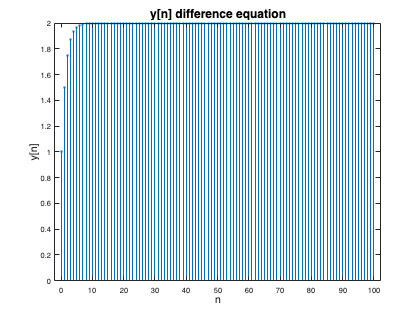

n = 0:100; % Time axis
x = ones (1 , 101) ; % Input signal
y = zeros (1 , 101) ; % Output

for idx = 1: length (n)
    if idx == 1
        y(idx)=x(idx);
    else
        y(idx) = 0.5*y(idx-1) + x(idx);
    end
end

stem(n, y, '.');
title('y[n] difference equation', 'FontSize', 16);
xlabel('n', 'FontSize', 14);
ylabel('y[n]', 'FontSize', 14);

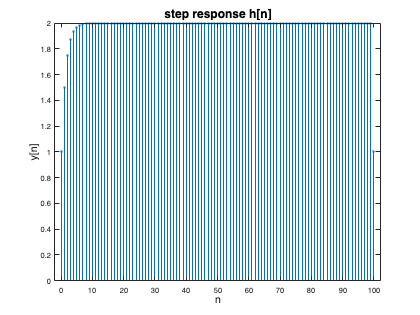

n = 0:100; % Time axis
h = (1/2).^n; % Impulse response h[n] = (1/2)^n
x = ones(1, 100); % Step input

y_step = conv(x, h); % Convolve input with h[n]
y_step = y_step(1:101); % Truncate to match time axis

stem(n, y_step, '.');
title('step response h[n]', 'FontSize', 16);
xlabel('n', 'FontSize', 14);
ylabel('y[n]', 'FontSize', 14);